# simple Bi-phase Materials

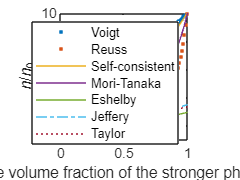

% viscosity ratio
  r = 10;
% volume fraction of the stronger phase  
  phi=0:0.01:1; 
% Voigt 
  etaV=phi.*r+(1-phi);
% Ruess
  etaR=(phi./r+(1-phi)).^-1;
% Eshelby
  etaE = 1 + 5.*phi.*(r-1)./(2*r+3);
% Mori-Tanaka  
  etaMT=((2+3.*phi).*r+1-phi)./(2.*(1-phi).*r+1+4.*phi);
% Self-Consistent   
  etaSC=zeros(size(phi));

  for jj=1:numel(phi)

      etaSC_0=etaV(jj);

      for kk=1:1000
          etaSC_new = 1+5.*phi(jj).*(r-1).*etaSC_0/(2*r+3*etaSC_0);
          err = abs(etaSC_new/etaSC_0 -1);
          etaSC_0 = etaSC_new;
          if err<=0.01
             break
          end
      end
      etaSC(jj)=etaSC_new;
  end
% Jeffery (1922), Einstein's result
  etaJ = 1+2.5.*phi;
% Taylor(1932)
  etaT=1+(5*r+2)/(2*(r+1)).*phi;
% Plot  
  figure('Name','Simple Bi-phase Results')
  plot(phi,etaV,'.',phi,etaR,'.',phi,etaSC,'-',phi,etaMT,'-',...
      phi,etaE,'-',phi,etaJ,'-.',phi,etaT,':')
  xlim([0 1])
  ylim([1,r])
  axis square
  xlabel('the volume fraction of the stronger phase')
  ylabel('\eta/\eta_0')
  legend('Voigt','Reuss','Self-consistent','Mori-Tanaka',...
        'Eshelby','Jeffery','Taylor')

% random distributed RDEs/inclusions with random shapes and orientations
  n = 200; % RDEs/inclusions number
  [a,ang]= RandAANG(5,n);
  q = Qvec(ang); 

% imposed strain rate
  E  =[0 1 0;1 0 0;0 0 0];
  EI = Inva(E);

% Self-consistent
  eta  = ones(n,1);
  Ne   = ones(n,1);
  S_SC = zeros(3,3,numel(phi));
  SI_SC= zeros(1,numel(phi));
  vis_SC = zeros(1,numel(phi),1);
  C_SC = zeros(3,3,3,3,numel(phi));
%   e_SC = zeros(3,3,n,numel(phi));
%   s_SC = zeros(3,3,n,numel(phi));
%   vis  = zeros(n,numel(phi));
  for kk = 1:numel(phi)
      if phi(kk)~=0
         ns = int64(n*phi(kk)); 
         eta(1:ns)=r.*ones(ns,1);
      end
      [S_bar,C_bar,~,~,~]= SC_homogenization(E, n, a, q, eta, Ne);
      S_SC(:,:,kk)=S_bar;
      C_SC(:,:,:,:,kk)=C_bar;
      SI_SC(kk)=Inva(S_bar);
      vis_SC(kk)= SI_SC(kk)/EI/2;
  end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


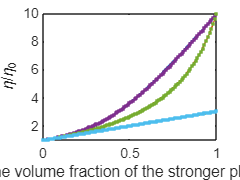

% Mori-Tanaka
  etak = r.*ones(n,1);
  etam = 1;  
  Nk = ones(n,1);
  Nm = 1;
  S_MT = zeros(3,3,numel(phi));
  SI_MT= zeros(1,numel(phi));
  vis_MT = zeros(1,numel(phi));
  C_MT= zeros(3,3,3,3,numel(phi));
%   e_MT = zeros(3,3,n,numel(phi));
%   s_MT = zeros(3,3,n,numel(phi));
%   Em = zeros(3,3,numel(phi));
%   Sm = zeros(3,3,numel(phi));
%   visk = zeros(n,numel(phi));
%   vism = zeros(1,numel(phi));
  for kk = 1:numel(phi)
      [S_bar,C_bar,~,~,~,~,~,~]=MT_homogenization(E,n,a,q,etak,etam,Nk,Nm,phi(kk));
      S_MT(:,:,kk)=S_bar;
      C_MT(:,:,:,:,kk)=C_bar;
      SI_MT(kk)=Inva(S_bar);
      vis_MT(kk)= SI_MT(kk)/EI/2;
  end

 % Eshleby approach 
  S_E = zeros(3,3,numel(phi));
  SI_E= zeros(1,numel(phi));
  vis_E = zeros(1,numel(phi));
  C_E= zeros(3,3,3,3,numel(phi));

  for kk=1:numel(phi)
      [S_bar,C_bar,e,s,vis]=Eshelby_approach(E,n,a,q,etak,etam,Nk,Nm,phi(kk));
      S_E(:,:,kk)= S_bar;
      C_E(:,:,:,:,kk)=C_bar;
      SI_E(kk)=Inva(S_bar);
      vis_E(kk)=SI_E(kk)/EI/2;
  end
  plot(phi,etaSC,'-',phi,etaMT,'-',phi,etaE,'-',phi,vis_SC,'.',phi,vis_MT,'.',phi,vis_E,'.')
  xlim([0 1])
  ylim([1,r])
  xlabel('the volume fraction of the stronger phase')
  ylabel('\eta/\eta_0')